# **Analyzing and Predicting Weather Data from ThingSpeak**

**Daksh Balyan 17ucs049**

**Mashu Ajmera 17dcs005**

**Mayank Aggarwal 17dcs006**

We use data from ThingSpeak channel 12397, which is a solar powered cellular Mathworks Weather Station in Natick, MA. It is being used to measure wind direction and speed, rain, temperature, humidity, pressure and light intensity of the area. ThingSpeak then utilises the weather data to display real-time charts. 

clear;
clc;
close all;
warning('off','all')

The above code block clears out any and all variables, text and figures that were left behind in the current workspace by a previous program run.

## 1. Preparation

In this section we read the data from the public channel 12397 into a "data" variable, with the help of the "thingSpeakRead" function. We read data for the last 7 days with 6 fields namely - TimeStamps, WindDirectionNorthDegress, WindSpeedmlh, Humidity, TemperatureF and PressureHg. The read data is stored in a table format. 

### a. Reading Data 

Set 'readChannelID' to the channel ID of the channel to read from.

readChannelID = 12397;
data = thingSpeakRead(readChannelID,'NumDays',7,'Fields',[1 2 3 4 5 6],'outputFormat','table');
availableFields=data.Properties.VariableNames'

availableFields = 7×1 cell array
    {'Timestamps'                }
    {'WindDirectionNorth0Degrees'}
    {'WindSpeedmph'              }
    {'Humidity'                  }
    {'TemperatureF'              }
    {'RainInchesminute'          }
    {'PressureHg'                }


### b. Removing Outliers

After reading, we do some preprocessing on the read data to make it more efficient by removing the outliers in the dataset. We do this by iterating over every field (besides the Timestamps) in the "data" variables and using the "isoutlier" function to return the index of the outlier data and then deleting it from the "data" variable. 

for i=2:7
    outlierDataIndex = isoutlier(data(:,i));
    cleanDataIndex = ~outlierDataIndex;
    data = data(cleanDataIndex,:);
end

## 2. Analysis

For analysing the pre-processed data we divided the task into six components wherein each we extract some useful infromation and compute other terms to get a better understanding of the trends/correlation in the dataset. 

### a. Max and Min temperature over past week

Calculating the Maximum and Minimum temperature 

[maxTempF,maxTempIndex] = max(data.TemperatureF);
[minTempF,minTempIndex] = min(data.TemperatureF);
 
timeMaxTemp = data(maxTempIndex,1);
timeMinTemp = data(minTempIndex,1);
 
disp(timeMaxTemp);

         Timestamps     
    ____________________

    13-Mar-2021 00:51:44



fprintf('Maximum temperature for the past week is %0.2f°F\n\n' , maxTempF);

Maximum temperature for the past week is 64.30°F



disp(timeMinTemp);

         Timestamps     
    ____________________

    15-Mar-2021 16:46:01



fprintf('Minimum temperature for the past week is %0.2f°F\n' , minTempF);

Minimum temperature for the past week is 15.00°F


### b. Average Humidity over past week

Calculating the average Humidity in the dataset.

avgHumidity = mean(data.Humidity);
fprintf('Average Humidity over past week is %0.2f g.m-3\n' , avgHumidity);

Average Humidity over past week is 34.46 g.m-3


### c. Correlation between all fields

Here, we use the "corrcoef" function of matlab to find correlation between all fields (except timestamp). The function return a matrix of correlation coefficients between elements A and B. The correlation coffecient is as follows:


$$\rho \left ( A, B \right ) = \frac{1}{N-1}\sum_{i=1}^{N}\left ( \frac{A_{i} - \mu_{A}}{\sigma _{A}} \right )\left ( \frac{B_{i} - \mu_{B}}{\sigma_{B}} \right )$$


Where $\mu_A$ and $\sigma_A$ are the mean and standard deviation of *A*, respectively, and $\mu_B$ and $\sigma_B$ are the mean and 

standard deviation of *B. *From the R matrix we see that the there is not high correlation between any field since no element (taking their aboslute value) is greater than 0.5, except ofcourse the diagonal elements which all have a value of 1. This because fields will have the maximum correlation with themselves.

tempdata=data(:,2:6);
matrixOfData=tempdata{:,:};
R = corrcoef(matrixOfData)

R =     1.0000    0.2353   -0.0296   -0.0482    0.0103
    0.2353    1.0000   -0.1106    0.1501    0.0379
   -0.0296   -0.1106    1.0000   -0.0249    0.0015
   -0.0482    0.1501   -0.0249    1.0000   -0.0049
    0.0103    0.0379    0.0015   -0.0049    1.0000


### d. Current Wind Chill

From the available fields data we calculate another field - "Wind Chill". This field is used to provide some more context to the Temperature and Wind Speed field by telling us the effect of low temperature winds on our body temperature. There are different formulas for calculating windchill, however the one formula which we are using is provided by [www.nws.noaa.gov/om/cold/wind_chill.shtml](www.nws.noaa.gov/om/cold/wind_chill.shtml) .

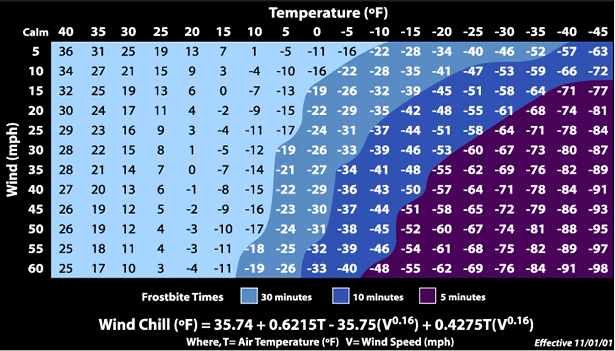

[temp,time] = thingSpeakRead(readChannelID,'Fields',4);
windSpeed = thingSpeakRead(readChannelID,'Fields',2);
windChill = 35.74 + (0.06215*temp) - (35.75*windSpeed^0.16) + (0.4275*temp*windSpeed^0.16); % WindChill formula
fprintf('Current WindChill value is %0.2f\n' ,windChill);

Current WindChill value is 16.64


### e. DewPoint

Here, we are calculating another term DewPoint to further our understanding on the available data. DewPoint is the temperature at which the water vapor in the air comes in equillibrium with the liquid water, i.e, water is evaporating and condesing at the same rate. There are again different ways to calculate DewPoint, but here we are using the Magnus Formula which is given as follows. 

source: [https://en.wikipedia.org/wiki/Dew_point#Measurement](https://en.wikipedia.org/wiki/Dew_point#Measurement)

[image: dewPoint.svg]

$\gamma \left(T,\textrm{RH}\right)$, is the gamma scalar quantity, RH is Relative Humidity, b and c are constants.

Recentdata = thingSpeakRead(readChannelID,'Fields',[1 2 3 4 6]);
tempF=Recentdata(4); % Temperature
humidity=Recentdata(3); % Relative Humidity
tempC = (5/9)*(tempF-32); % TConverting temp to Celsius
b = 17.62; % constant
c = 243.5; % constant
gamma = log(humidity/100) + b*tempC / (c+tempC); % gamma constant
dewPointC = c*gamma ./ (b-gamma); % dewpoint in celsius
dewPointF = (dewPointC*1.8) + 32; % dewpoint in farenheit
fprintf('Current dewPointF value is %0.2f°F\n' ,dewPointF);

Current dewPointF value is 30.98°F


## **3. Visualizations**

Data visualization is the next step towards getting a better understanding of the dataset, where the data is graphically represented using charts, graphs and maps. Through visualising our data we using graphs we are able to understand trends and find patterns between different fields more intuitively. 

### a. Temperature and WindSpeed

This section plots the temperature and WindSpeed on the Y-axis with respect to the date of the data produced. The temperature (in Farenheit) is plot in blue and WindSpeed (in mph) in orange.  

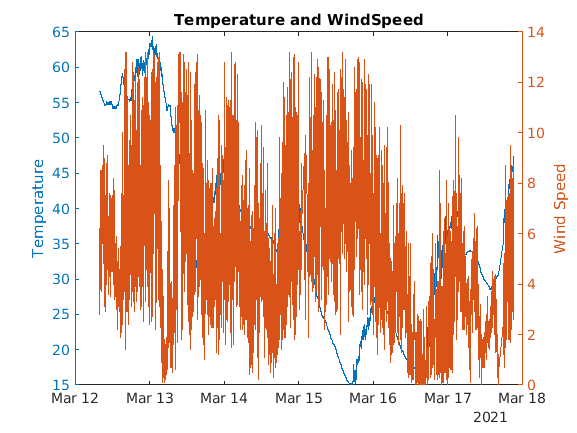

yyaxis left
plot(data.Timestamps, data.TemperatureF);
ylabel('Temperature');
yyaxis right
plot(data.Timestamps, data.WindSpeedmph);
ylabel('Wind Speed');
title('Temperature and WindSpeed')

Looking at the graph we infer that the trend that temperature decreases along with a very consistent high windspeed.

### b. Acquire and Process Weather Data on a Rainy Day

In this component, we are will be analyzing the rain conditions to do which we will use the data retrieved from the weather station on a known rainy day. The rainfall gauge that we used is a self-emptying one that rotates and empties when 0.01 inches of rain have fallen. The Arduino code counts the number of times the meter has emptied every minute and sends the appropriate rainfall value to ThingSpeak.

[d,t,ci] = thingSpeakRead(12397,'DateRange',[datetime(2014,6,4,0,0,0),datetime(2014,6,6,0,0,0)]); % get data
baro = d(:,6); % pressure
extraData = rem(length(baro),60); % computes excess points beyond the hour
baro(1:extraData) = []; % removes excess points so we have even number of hours
rain = d(:,5); % rainfall from sensor in inches per minute

From the data it can be seen that we received 0.32 inches. To get a better idea of when the maximum rainfall occurred we can convert the data to hourly data as shown below.

rain(1:extraData) = [];
t(1:extraData) = [];
rainHourly = sum(reshape(rain,60,[]))'; % convert to hourly summed samples
maxRainPerMinute = max(rain)

maxRainPerMinute = 0.0100

june5rainfall = sum(rainHourly(25:end)) % 24 hours of measurements from June 5

june5rainfall = 0.3200

baroHourly = downsample(baro,60); % hourly samples
timestamps = downsample(t,60); % hourly samples

**Visualize the Hourly Rain and Pressure Data and Find Pressure Trend**

Using the calculated hourly rain and the barometric pressure on the three particular date we plot the data using graphs with pressure and rainfall on the Y-axis and Date on the X-axis. Using MatLab functions we then fit a trend line to the barometric pressure data and the data plotted alongside the rainfall is analysed.

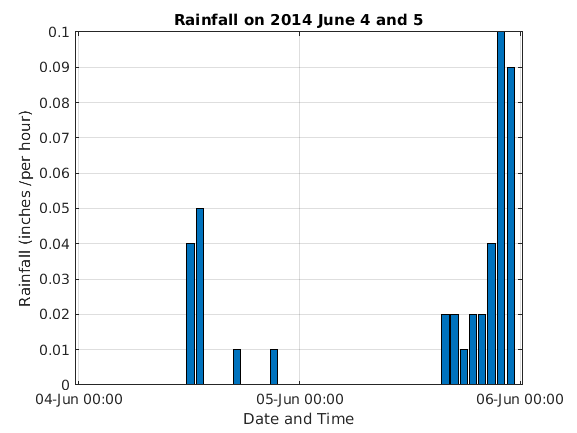

figure(3)
bar(timestamps,rainHourly) % plot rain
xlabel('Date and Time')
ylabel('Rainfall (inches /per hour)')
grid on
datetick('x','dd-mmm HH:MM','keeplimits','keepticks')
title('Rainfall on 2014 June 4 and 5')

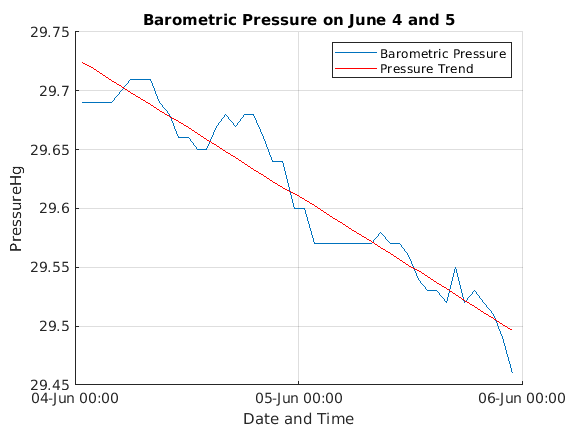

figure(4)
hold on
plot(timestamps,baroHourly) % plot barometer pressure
xlabel('Date and Time')
ylabel('PressureHg')
grid on
datetick('x','dd-mmm HH:MM','keeplimits','keepticks')
detrended_Baro = detrend(baroHourly);
baroTrend = baroHourly - detrended_Baro;
plot(timestamps,baroTrend,'r') % plot trend
hold off
legend('Barometric Pressure','Pressure Trend')
title('Barometric Pressure on June 4 and 5')

After the analysis we infer  from figure 3 and 4 that the barometric pressure does indeed drop prior to our heavy rainfall event as backed by scietific principles.

### c. Compare Temperature Data from last Three Days

In this section, we use `thingSpeakRead` to retrieve the data for each day. Specifying the `'DateRange'` allows you to set the stop and start dates for your data collection. 

TemperatureFieldID = 4;
temperatureDay1 = thingSpeakRead(readChannelID,'Fields',TemperatureFieldID,'dateRange',...
    [datetime('today')-days(1),datetime('today')]); 

temperatureDay2 = thingSpeakRead(readChannelID,'Fields',TemperatureFieldID,'dateRange',...
    [datetime('today')-days(2),datetime('today')-days(1)]); 

temperatureDay3 = thingSpeakRead(readChannelID,'Fields',TemperatureFieldID,'dateRange',...
    [datetime('today')-days(3),datetime('today')-days(2)]);

We then in the following code create an array of durations that matches the length of each dataset. The length of each series fluctuates depending on the exact start time. The measurements are taken every minute, but are not aligned on each day.

myTimes1=minutes(1:length(temperatureDay1));
myTimes2=minutes(1:length(temperatureDay2));
myTimes3=minutes(1:length(temperatureDay3));

Using `plot` and `hold` we generate the plots, then we set the legend to differentiate the series using `legend`. Then provide axis and chart titles with `xlabel`, `ylabel`, and `title`.

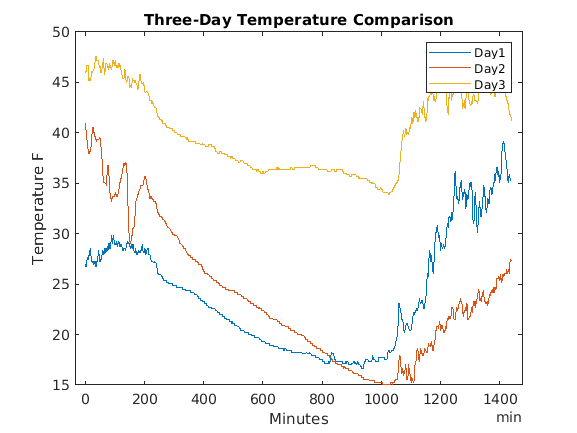

plot(myTimes1,temperatureDay1, myTimes2,temperatureDay2, myTimes3,temperatureDay3);
legend({'Day1','Day2','Day3'});
xlabel('Minutes')
ylabel('Temperature F');
title('Three-Day Temperature Comparison');

## 4. Predictions

### Forecasting Future Values Using the data from previous week

Here we have empirically chosen the model complexity which best fit our data to decide the order of the regression polynomial.

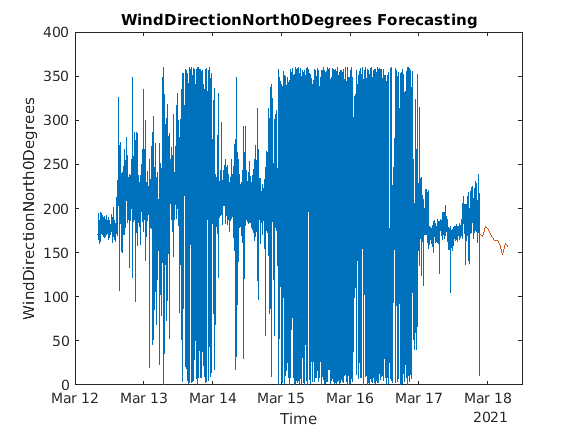

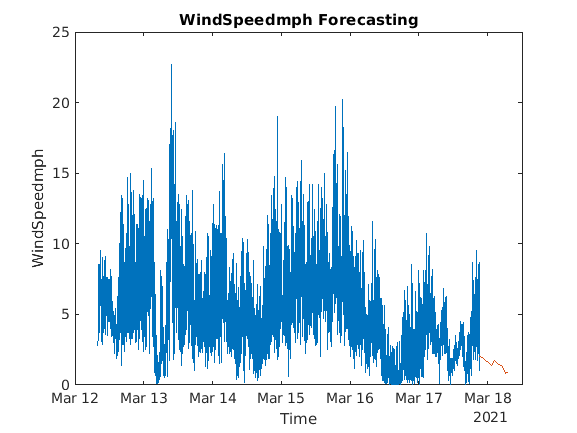

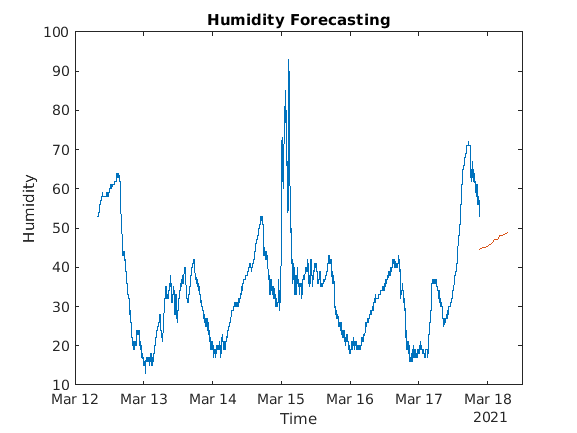

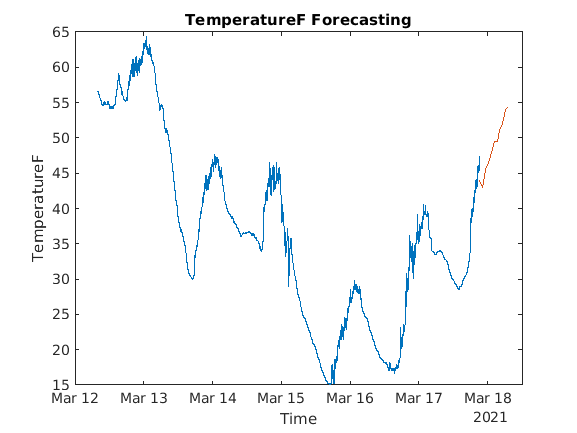

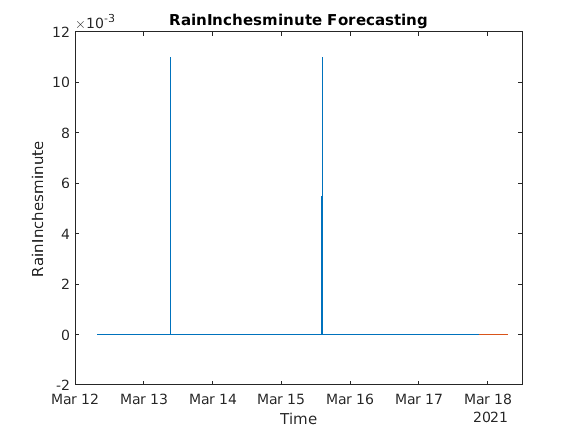

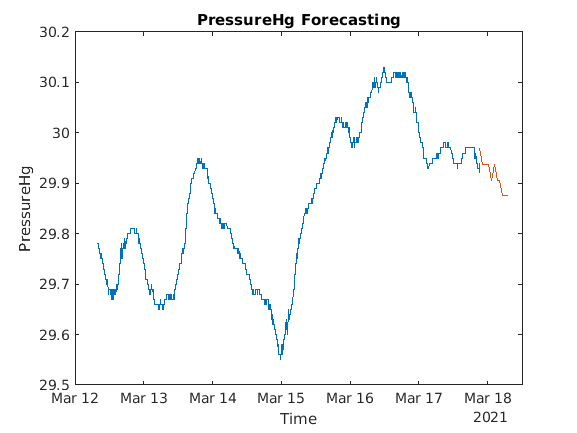

order=[20 12 5 30 12 14]; % model complexity
for i=1:6
    [value,time] = thingSpeakRead(readChannelID,'Fields',i,'NumDays',7); 
    
    x=datenum(time);
    t=value';
    x=x';
    p = polyfit(x,t,order(i));
    
    future_time=datetime('now') + hours(0:10);
    future = datenum(future_time);
    
    forecasted_values = polyval(p,future);
    
    figure
    plot(time,t,'-')
    hold on
    plot(future_time,forecasted_values)
    hold off
    title(append(string(availableFields(i+1)),' Forecasting'))
    ylabel(string(availableFields(i+1)))
    xlabel('Time')
end